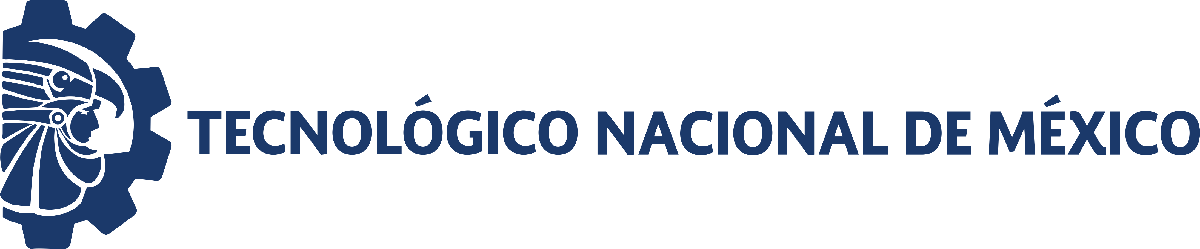                                 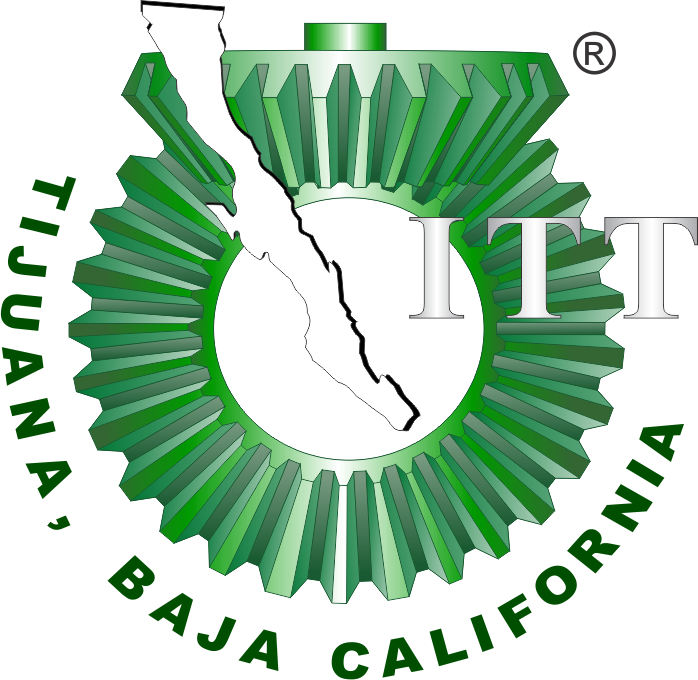

# Práctica dos: Sistema Respiratorio 

**Departamento de Ingeniería Eléctrica y Electrónica, Ingeniería Biomédica**

**Tecnológico Nacional de México [TecNM - Tijuana], Blvd. Alberto Limón Padilla s/n, C.P. 22454, Tijuana, B.C., México**

## Información general

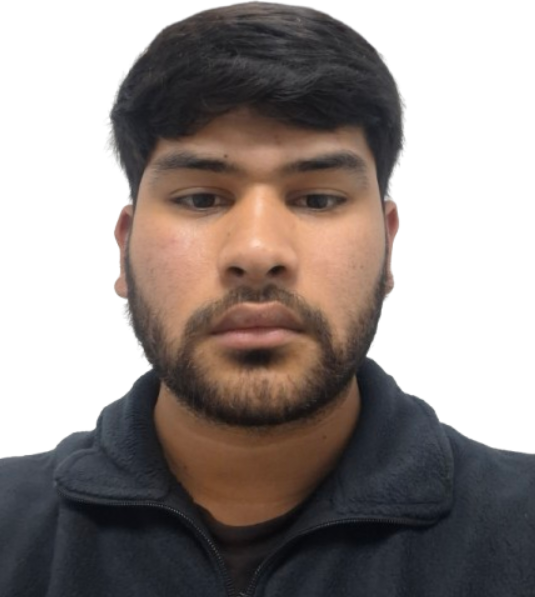

Nombre del alumno: Tapia Garcia Jahzeel Abisai

Número de control: 22210798

Correo institucional: l22210798**@tectijuana.edu.mx**

Asignatura: **Modelado de Sistemas Fisiológicos**

Docente: **Dr. Paul Antonio Valle Trujillo; paul.valle@tectijuana.edu.mx **

## Datos de la simulación

clc; clear; close all; warning('off','all')
tend = '10';
file = 'P2Simulink';
open_system(file);
parameters.StopTime = tend;
parameters.Solver = 'ode15s';
parameters.MaxStep = '1E-3';
parameters.StopTime = '30';

## Rendimiento del controlador

kP = 188.9108

kI = 4785.7956

kD =  0.9313

N = 18502.6144

Setting Time = 0.0216 s

Overshoot = 2.61%

Peak = 1.03

## **Respiración normal**

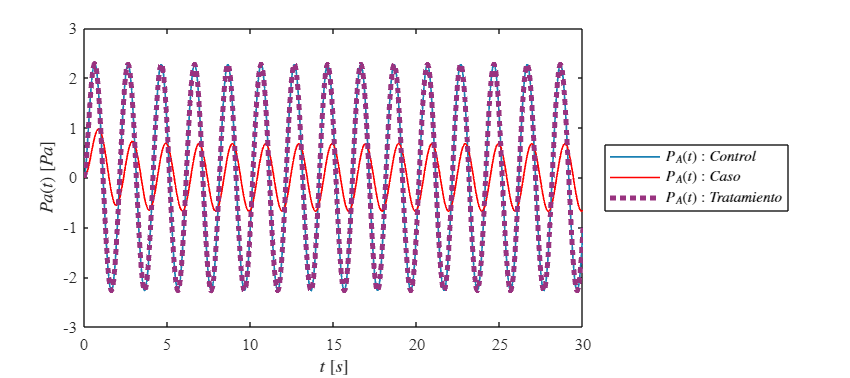

Signal = 'Respiracion normal';
set_param('P2Simulink/Pao(t)','sw','1');
set_param('P2Simulink/PID Controller1','P','188.9108');
set_param('P2Simulink/PID Controller1','I','4785.7956');
set_param('P2Simulink/PID Controller1','D','0.9313');
N = sim(file,parameters);
plotsignals(N.t,N.PAx,N.PAy,N.PAz,Signal)

## Respiracion anormal

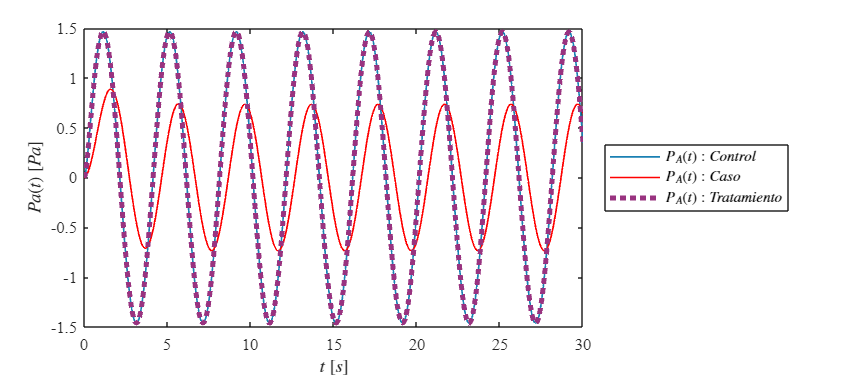

Signal = 'Respiracion Anormal';
set_param('P2Simulink/Pao(t)','sw','0');
set_param('P2Simulink/PID Controller1','P','188.9108');
set_param('P2Simulink/PID Controller1','I','4785.7956');
set_param('P2Simulink/PID Controller1','D','0.9313');
N = sim(file,parameters);
plotsignals(N.t,N.PAx,N.PAy,N.PAz,Signal)

## Respuesta a las señales

function plotsignals(t,PA,Pao,PID,Signal)
set(figure(),'Color','w')
set(gcf,'Units','Centimeters','Position',[1,1,18,8])
set(gca,'FontName','Times New Roman')
fontsize(10,'points')
    rojo=[1,0,0];
    morado=[.6,.2,.5];
    azul=[.1,.5,.7];
hold on; grid off; box on;

plot(t,PA,'LineWidth',1,'Color',azul)
plot(t,Pao,'LineWidth',1,'Color',rojo)
plot(t,PID,':','LineWidth',3,'Color',morado)

  xlabel('$t$ $[s]$','Interpreter','Latex')
    ylabel('$Pa(t)$ $[Pa]$','Interpreter','Latex')

L = legend('$P_{A}(t): Control$','$P_{A}(t): Caso$','$P_{A}(t): Tratamiento$');  
set(L, 'Interpreter', 'Latex', 'Location', 'EastOutside', 'Box', 'on');

end